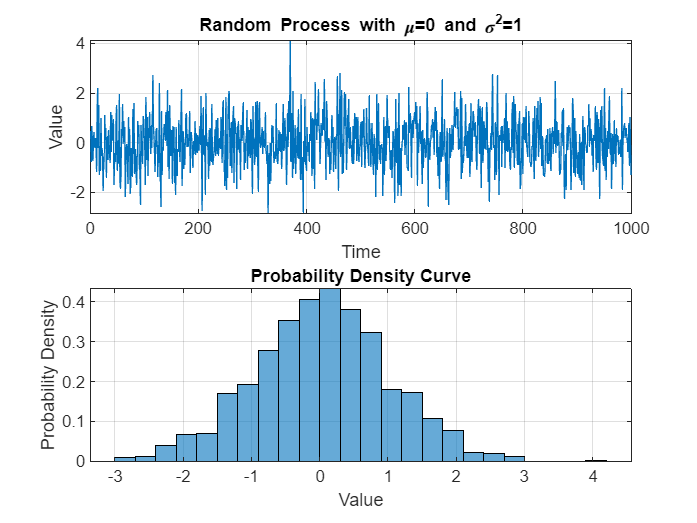

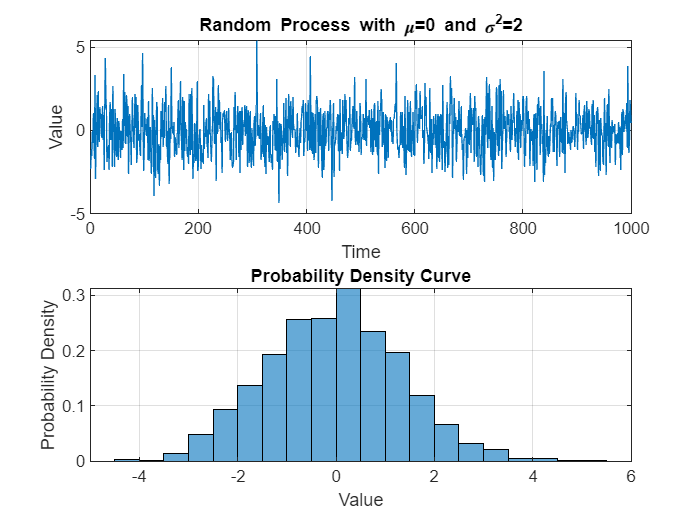

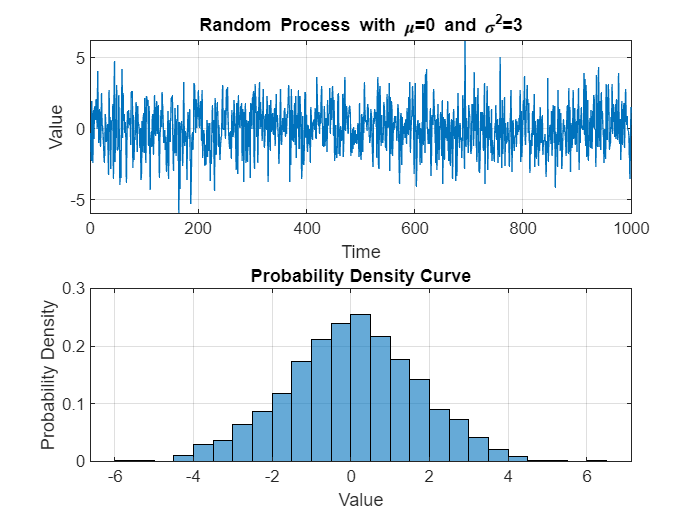

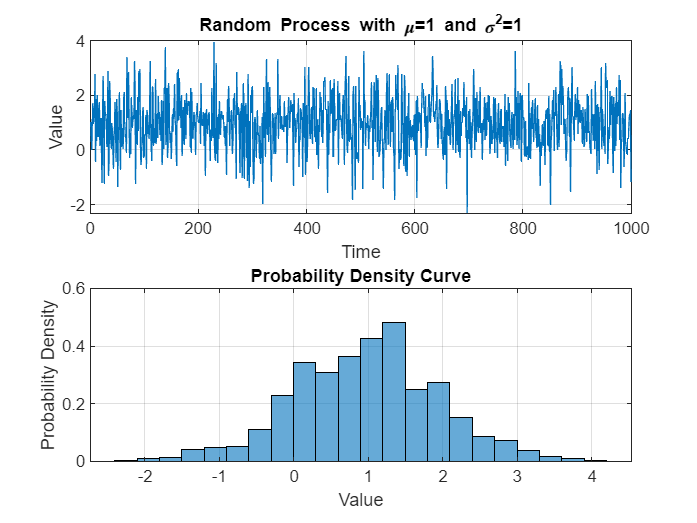

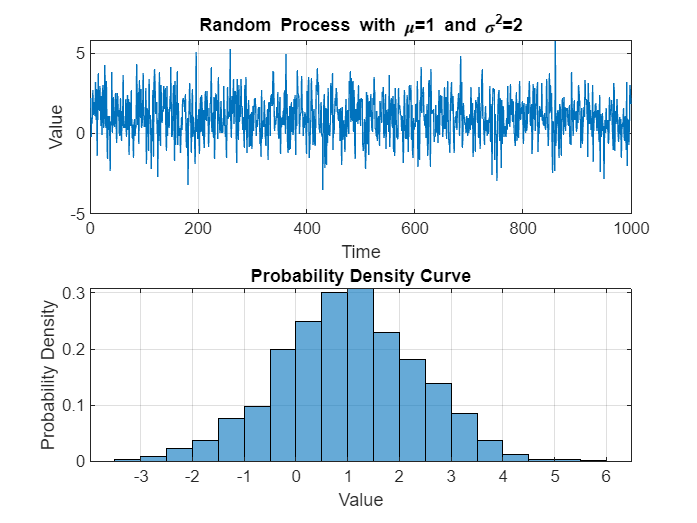

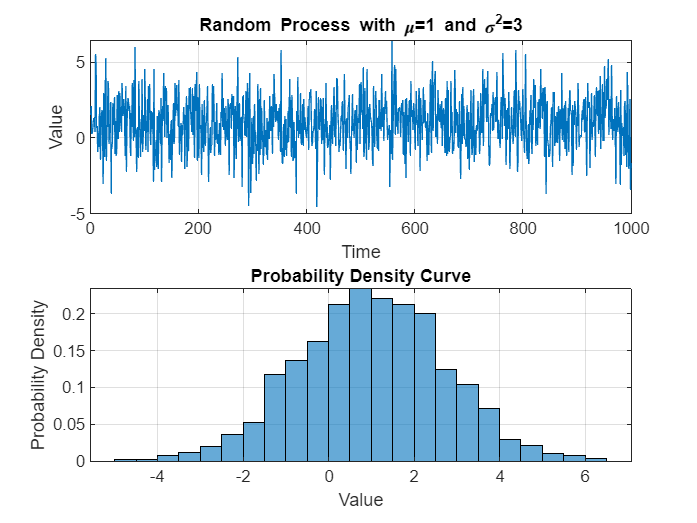

clear all; close all; clc;

% Parameters
num_samples = 1000;  % Number of samples
mean_values = [0, 0, 0, 1, 1, 1];  % Different mean values
variance_values = [1, 2, 3, 1, 2, 3];  % Different variance values

% Generate the time axis (x-axis)
time_axis = 1:num_samples;

for i = 1:length(mean_values)
    mean_val = mean_values(i);
    sigma = sqrt(variance_values(i));
    
    % Generate random samples from a normal distribution with specified mean and variance
    random_samples = sigma * randn(1, num_samples) + mean_val;

    % Create a new figure for each random process
    figure;
    
    % Plot the random process
    subplot(2, 1, 1);
    plot(time_axis, random_samples);
    xlabel('Time');
    ylabel('Value');
    title(['Random Process with \mu=', num2str(mean_val), ' and \sigma^2=', num2str(sigma^2)]);
    grid on;

    % Plot the histogram and probability density curve
    subplot(2, 1, 2);
    histogram(random_samples, 'Normalization', 'pdf');
    xlabel('Value');
    ylabel('Probability Density');
    title('Probability Density Curve');
    grid on;
end